# Iteration 1

## Load traces

Edit the following variables for the current recording.

- trDir1: the folder of the saved traces.

- tWin: [0, end_of_recording_in_sec]

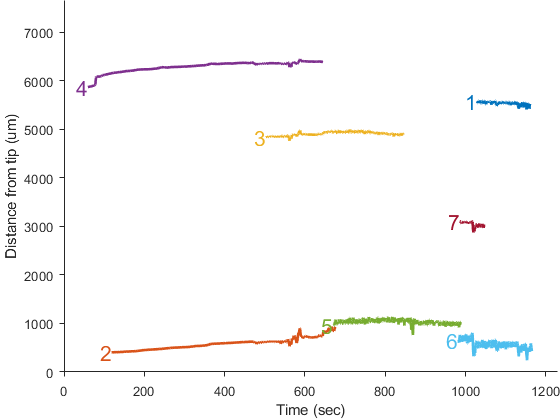

% Find trace files
trDir1 = 'MTracer_NP50_B3_2023-02-08_10-28-19';
trSearch1 = MBrowse.Dir2Table(fullfile(trDir1, 'MTracerTrace*.mat'));
trPaths1 = fullfile(trSearch1.folder, trSearch1.name);

% Load traces
tbTr1 = table;
for i = numel(trPaths1) : -1 : 1
    load(trPaths1{i});
    dataTb = sortrows(dataTb, 't');
    ind = dataTb.isDone;
    tbTr1.time{i} = dataTb.t(ind);
    tbTr1.y{i} = dataTb.y(ind);
end

% Resample traces
tWin = [0 1230];
tBin = 0.02;
tbTr1 = NP.Motion.ResampleTraces(tbTr1, tWin(1) : tBin : tWin(2));

% Plot traces with labels
MPlot.Figure(301); clf
NP.Motion.PlotTraces(tbTr1.time, tbTr1.Y, 'ShowLabel', true);
xlim(tWin)
ylim([0 7660])

## Fit models for movement scaling across depth

Play with the following variables to achieve reasonable scaling.

- ind: The indices of traces to include. They should have decent amount of overlaps in time.

- scaleMathod: 'makima' for nonlinear scaling and 'linear' for linear scaling.

See function help for more details.

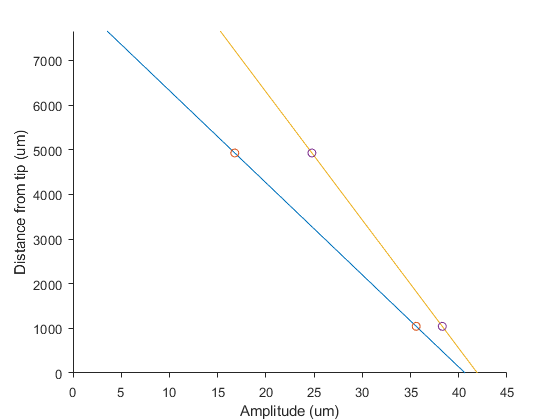

% Specify the traces we want to use for the fits
ind = [3 5];
% ind = [2 4];
% ind = [2 3 4];

% Fit scaling models
scaleMathod = 'makima';
[F1fluc, F1drift] = NP.Motion.FitAmpScaling(tbTr1.Y(:,ind), 1/tBin, scaleMathod);

% Plot the two scaling functions
MPlot.Figure(401); clf
NP.MotionPlot.AmpScaling(F1fluc); % blue
NP.MotionPlot.AmpScaling(F1drift); % yellow

Save the models to "F1.mat" if we are happy about them

save('F1', 'F1fluc', 'F1drift');

## Extrapolate traces

% Extrapolation
t = tbTr1.time;
Y = tbTr1.Y;
% Ye = NP.Motion.ExtrapolateTraces(Y, F1fluc, F1drift);  % use both fluctuation and drift scaling model
Ye = NP.Motion.ExtrapolateTraces(Y, F1fluc, 1);         % use fluctuation scaling model only
% Ye = NP.Motion.ExtrapolateTraces(Y, 1, F1drift);       % use drift scaling model only

% Fill the rest with straight lines
Ye = NP.Motion.ExtrapolateTrace(Ye, zeros(size(t)), F1fluc);

% Make a new table
tbTrExt1 = tbTr1;
tbTrExt1.Y = Ye(:,:); % only keep key traces

## Fit spatial-temporal interpolant

Edit the following variables for the current recording.

- t0: Where in time (sec) do we want to register everywhere else to.

t0 = 800;
F2 = MTracer.MotionInterpolant(t, tbTrExt1.Y, t0);
save('F2', 'F2');

## Plot motion estimation

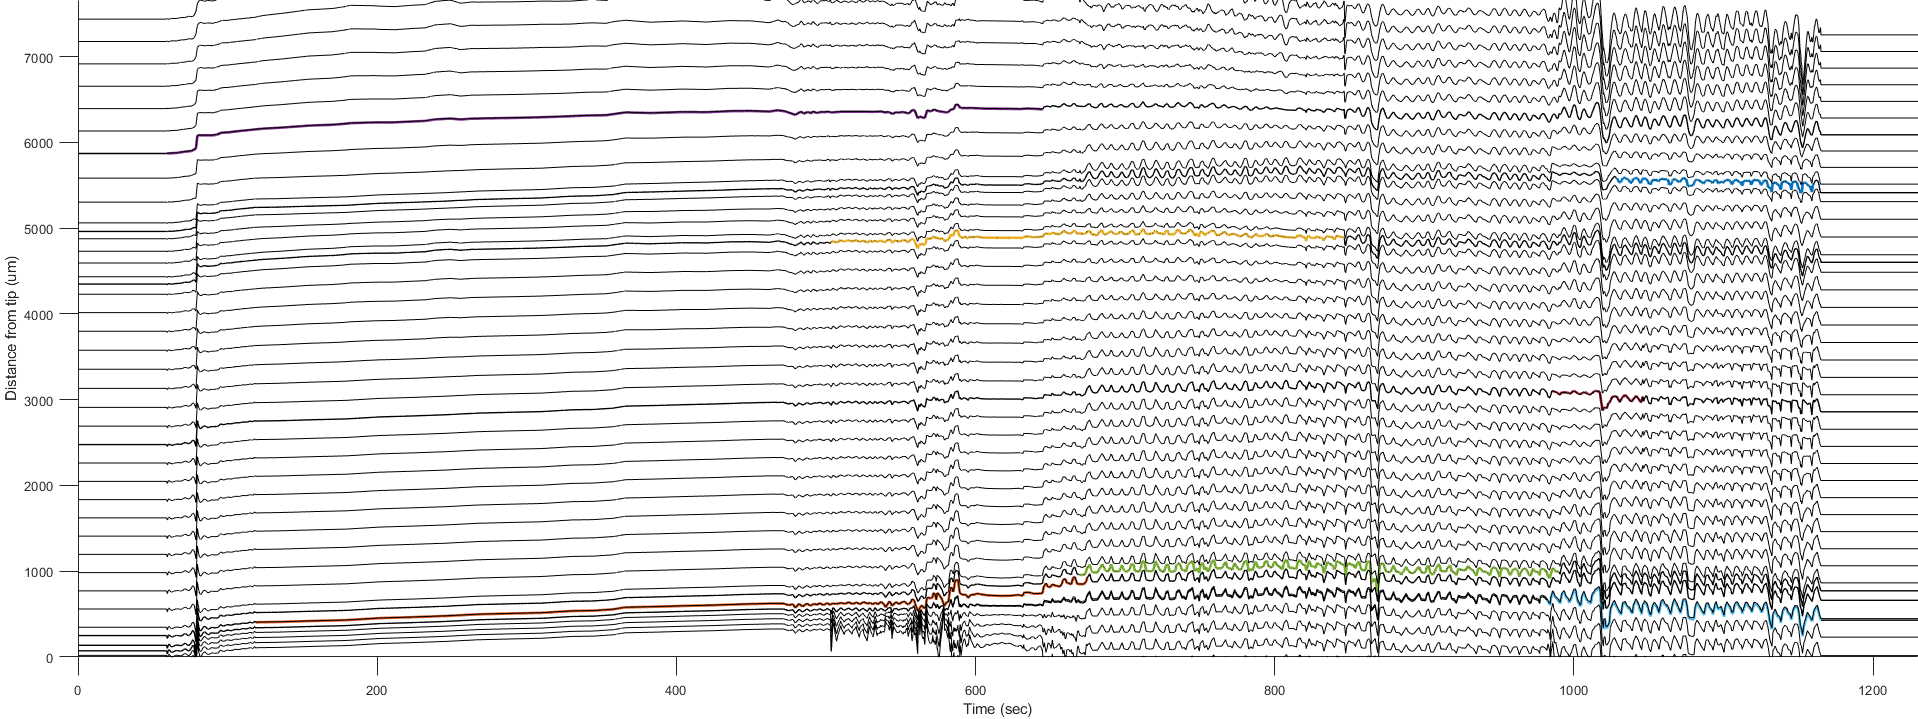

f = MPlot.Figure(311); clf
f.Position(3:4) = [1920 720];
% f.Visible = 'on';

NP.Motion.PlotTraces(tbTrExt1.time, tbTrExt1.Y, [0 0 0], 'LineWidth', 1);
NP.Motion.PlotTraces(tbTr1.time, tbTr1.Y);

[Tq, Yq, dYq] = F2.ComputeDispField();
plot(Tq, Yq, 'Color', [0 0 0 .25], 'HitTest', 'off');

xlim(tWin)
ylim([0 7660])

## Test correction on anchor traces

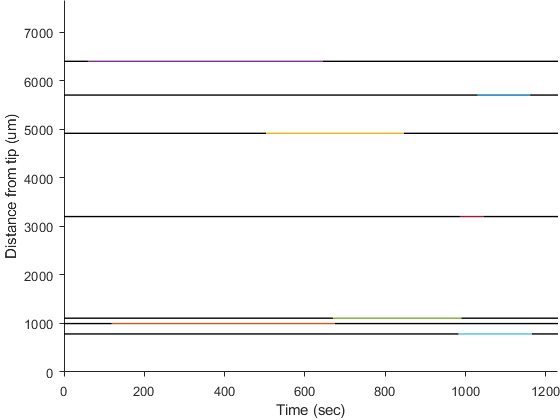

MPlot.Figure(410); clf

tbTrExtK1 = tbTrExt1;
tbTrExtK1.Y = F2.CorrectDepths(t, tbTrExt1.Y);
NP.Motion.PlotTraces(tbTrExtK1.time, tbTrExtK1.Y, 'k', 'LineWidth', 1);

tbTrK1 = tbTr1;
tbTrK1.Y = F2.CorrectDepths(t, tbTr1.Y);
NP.Motion.PlotTraces(tbTrK1.time, tbTrK1.Y, 'LineWidth', 1);

axis tight xy
ax = gca;
ax.LooseInset = [0 0 0 0];
ax.YLim = [0 7660];